# Osservatore dello stato

L'osservatore di stato è un sistema dinamico con lo scopo di stimare l'evoluzione di stato di un sistema da osservare.

Consideriamo il sistema $P$ nello spazio degli stati:


$$\dot{x}=Ax+Bu$$



$$y=Cx+Du$$


in cui $D=0$.

clear all;close all;clc;
addpath('../modelli')
Jm=2e-2;
Jc=10e-2;
k=1000;
h=0.3;
hm=.001;
model=ElasticSystemModel(Jm,Jc,k,h,hm); % posizione del motore

P=model(1,1);
A=P.A;
B=P.B;
C=P.C;
D=P.D;

## Osservatore di Luenberger

Vogliamo realizzare un osservatore di Luenberger per stimare $x$, **creo** il sistema osservatore


$$\dot{x}_o=Ax_o+Bu+L(y-y_o)=(A-LC)x_o+Bu+Ly$$



$$y_o=Cx_o+Du$$


Devo scegliere $L$ per far si che $x_o \rightarrow x$ con la dinamica che voglio

#### Posso farlo?

Per poter osservate tutto lo stato, il rango della matrice di osservabilità deve essere massimo

if (rank(obsv(P))==order(P))
    disp('Sistema osservabile')
else
    disp('Sistema non completamente osservabile. Stati non ossservabili = ',order(P)-rank(obsv(P)))
    no=order(P)-rank(obsv(P));

riscrivo il sistema per evidenziare la parte non osservabile

    [Abar,Bbar,Cbar,T,k] = obsvf(P.A,P.B,P.C)
    disp(Abar)
    return
end

Sistema osservabile


#### Come farlo? 

#### piazzamento autovalori

Scelgo dove mettere gli autovalori. Autovalori più negativi corrispondono a stime più rapide ma più soggetta ai rumori. Per limiti dell'algoritmo place, gli autovalori devono essere diversi ma possibilmente molto vicini fra loro.

p_oss=[-10,-11,-12,-13]

p_oss =    -10   -11   -12   -13


L=place(A',C',p_oss)'

L = 	1.0e+04 *

    0.0028
   -0.0005
   -5.9714
    1.1943


open('osservatore_1.slx')


**Cosa fare con le coppie non modellate?**

Aggiungiamo l'effetto di un attrito Coulombiano $\tau_{friction}=-3sign(x_3)$, approssimo $sign(x_3)=tanh(10x_3)$ per ridurre i problemi numerici.

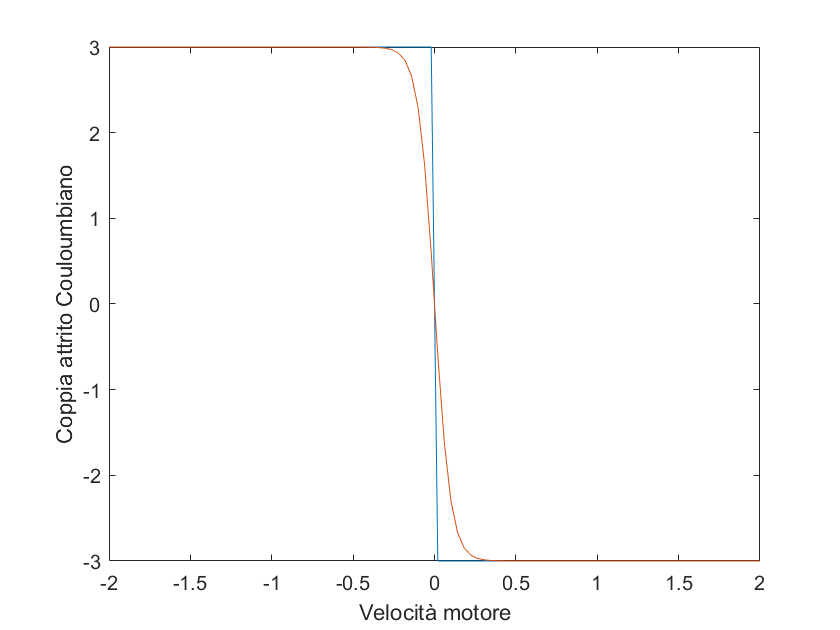

x=linspace(-2,2);
plot(x,-3*sign(x),x,-3*tanh(10*x));
xlabel('Velocità motore');
ylabel('Coppia attrito Couloumbiano')

open('osservatore_2.slx')